# GRAPHS

close all;
%--- Define for the system
n =  4; p = 3;  u = 1; % 4 states, 3 outputs and 1 input
States = {'Chassis Position','Chassis Velocity','Wheel Position', 'Wheel velocity'};
Outputs  = {'Chassis Position','Suspension Deflection','Chassis Acceleration'};
%Inputs = {''};

## Initial Condition Response

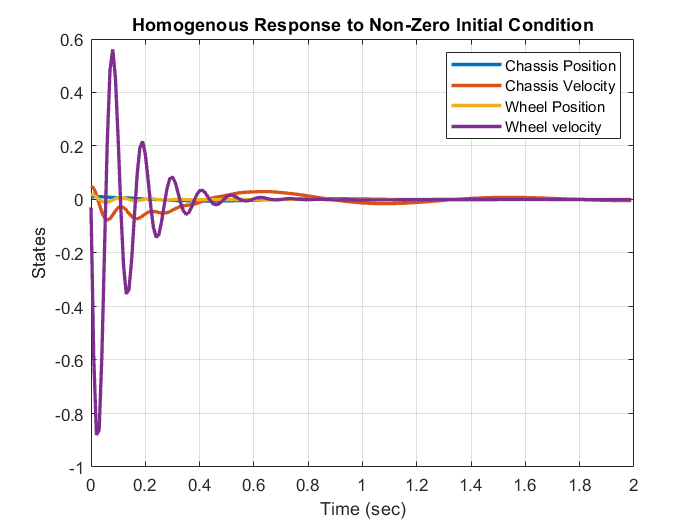

%-- States 
figure;
for i = 1:n
plot(t,X_ic(:,i),'LineWidth',2); hold on;grid on; % Plots the i state for all time samples
end
title('Homogenous Response to Non-Zero Initial Condition');
xlabel('Time (sec)');ylabel('States');
legend(States);

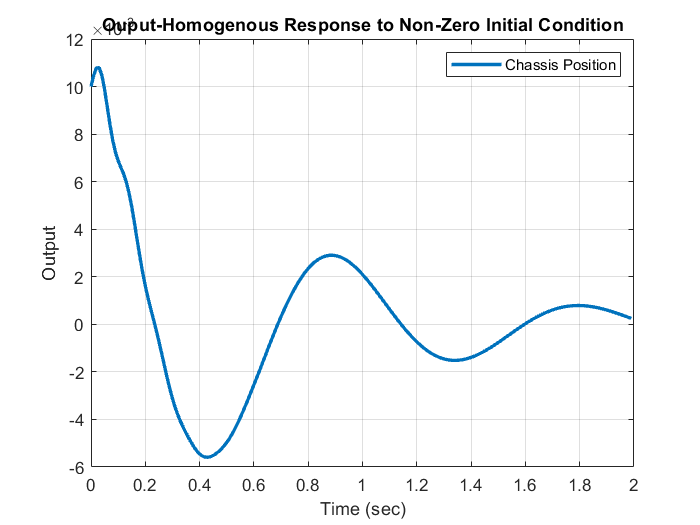

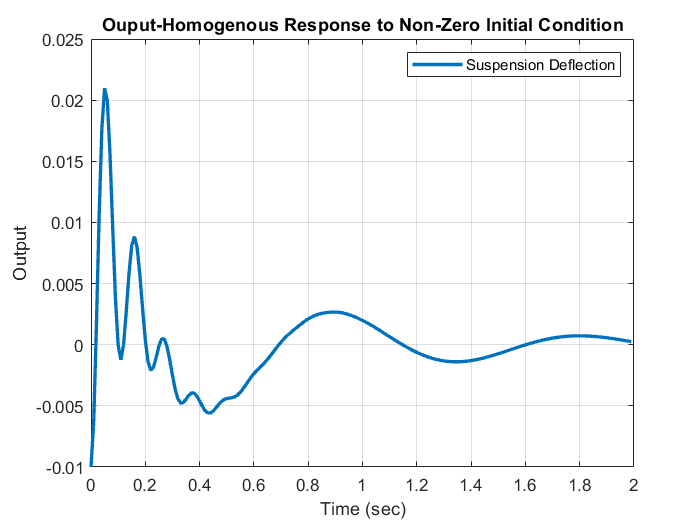

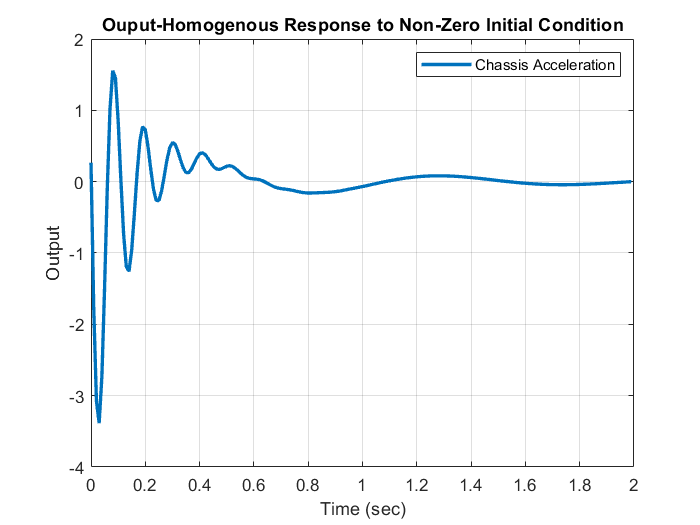

%-- Ouputs 
for i = 1:p
    figure;
plot(t,Y_ic(:,i),'LineWidth',2); hold on;grid on; % Plots the i state for all time samples
title('Ouput-Homogenous Response to Non-Zero Initial Condition');
xlabel('Time (sec)');ylabel('Output');
legend(Outputs(i))
end

## Forced Condition Response

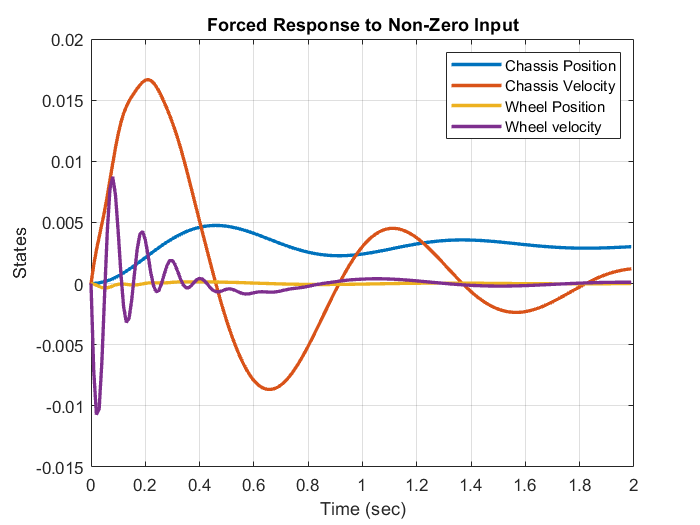

close all;
%-- States 
figure;
for i = 1:n
plot(t,X_f(:,i),'LineWidth',2); hold on;grid on; % Plots the i state for all time samples
end
title('Forced Response to Non-Zero Input');
xlabel('Time (sec)');ylabel('States');
legend(States);

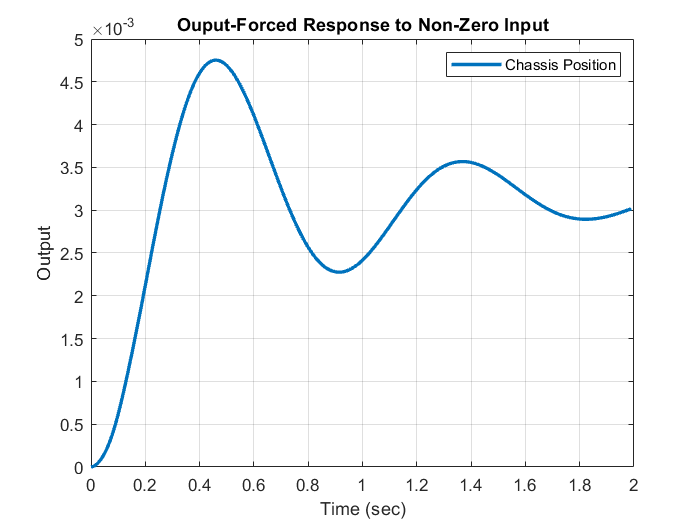

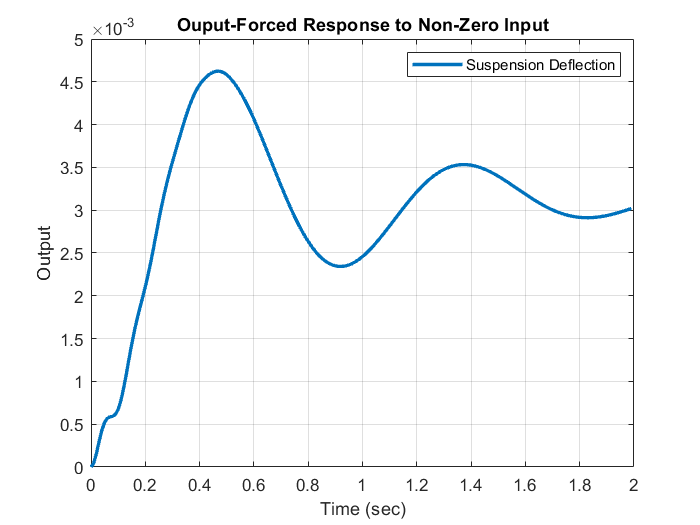

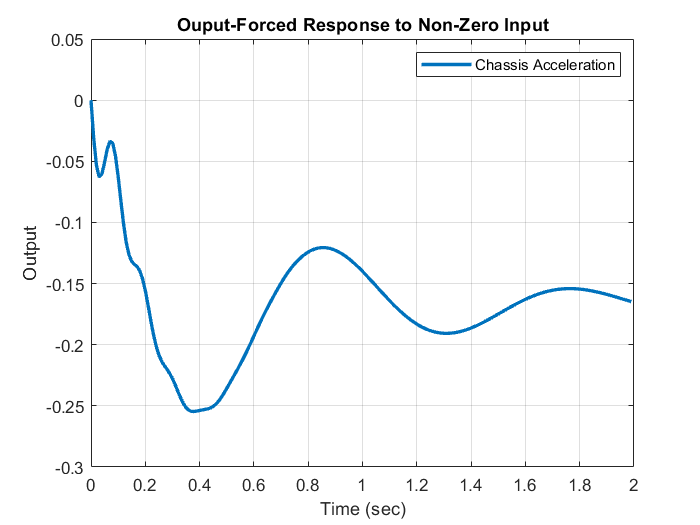

%-- Ouputs 
for i = 1:p
    figure;
plot(t,Y_f(:,i),'LineWidth',2); hold on;grid on; % Plots the i state for all time samples
title('Ouput-Forced Response to Non-Zero Input');
xlabel('Time (sec)');ylabel('Output');
legend(Outputs(i))
end

## Total Response

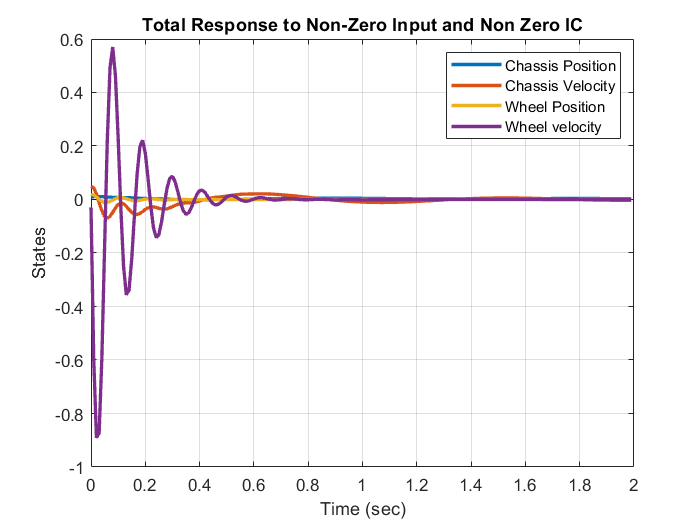

close all;
%-- States 
figure;
for i = 1:n
plot(t,X_t(:,i),'LineWidth',2); hold on;grid on; % Plots the i state for all time samples
end
title('Total Response to Non-Zero Input and Non Zero IC');
xlabel('Time (sec)');ylabel('States');
legend(States);

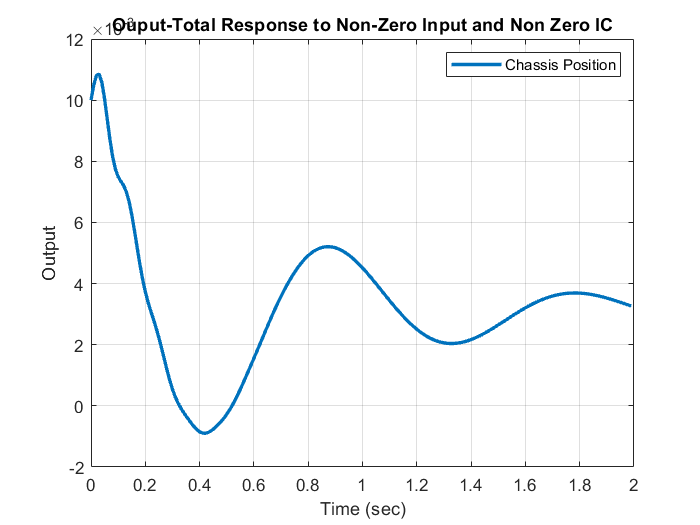

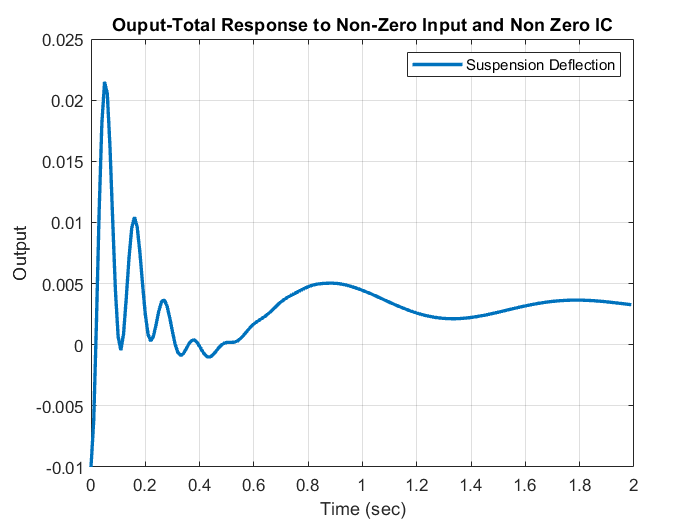

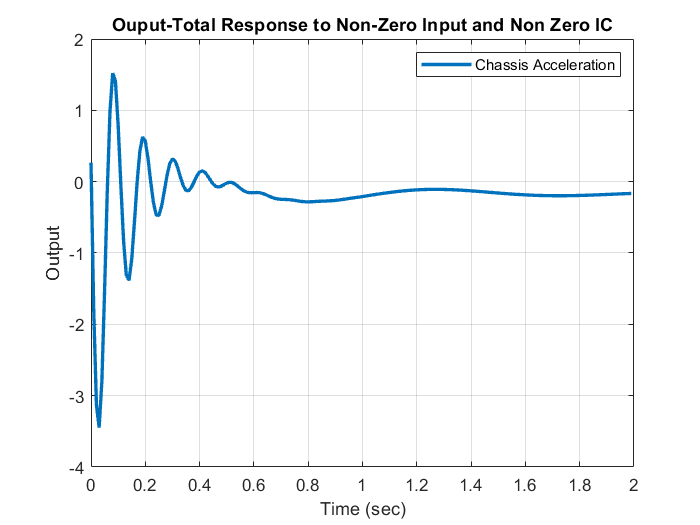

%-- Ouputs 
for i = 1:p
    figure;
plot(t,Y_t(:,i),'LineWidth',2); hold on;grid on; % Plots the i state for all time samples
title('Ouput-Total Response to Non-Zero Input and Non Zero IC');
xlabel('Time (sec)');ylabel('Output');
legend(Outputs(i))
end

## Total Response = Homogenous Response + Forced Response

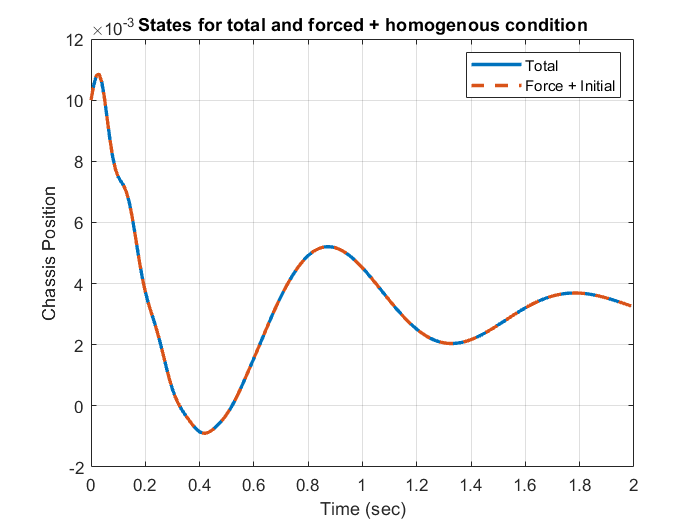

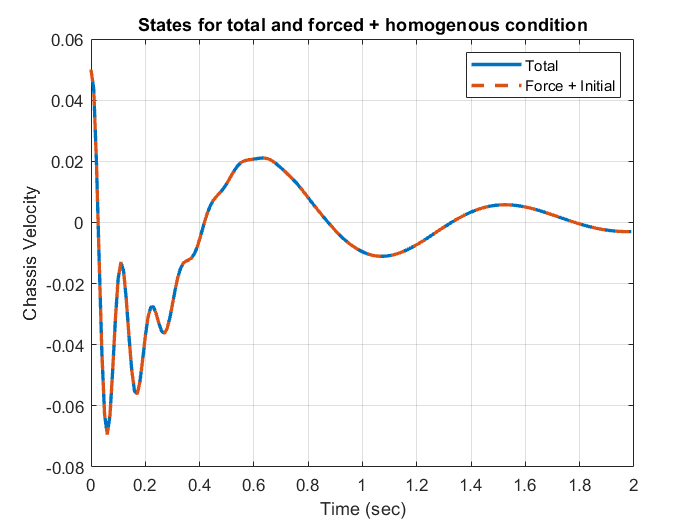

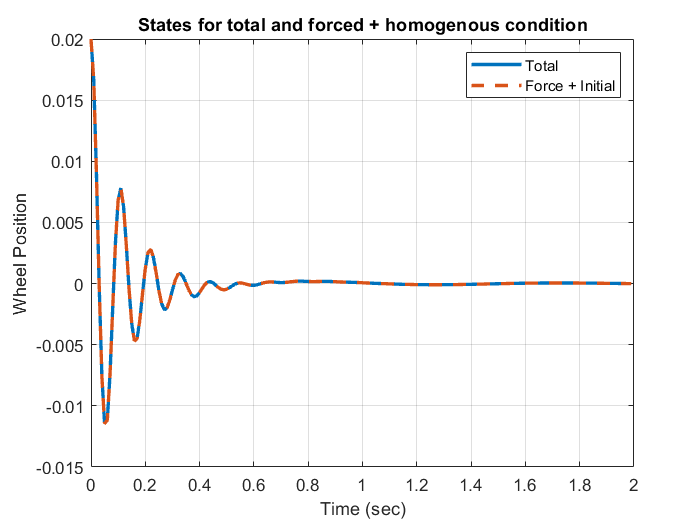

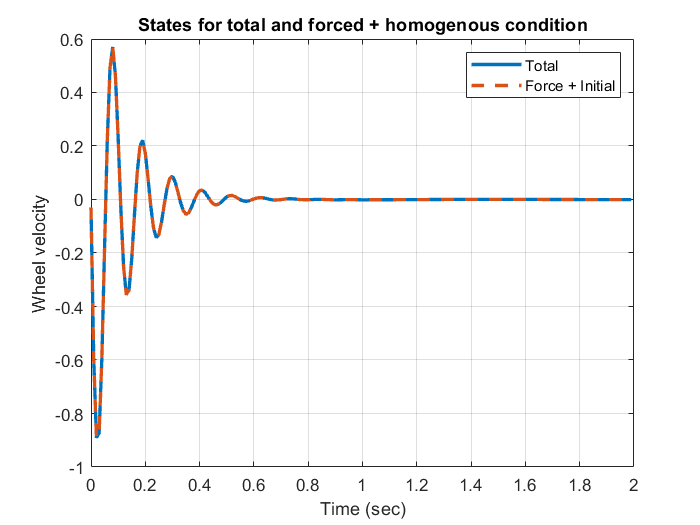

close all;
%-- States 
for i = 1:n
figure;
plot(t,X_t(:,i),'LineWidth',2); hold on;grid on; % total Response
plot(t,(X_f(:,i)+X_ic(:,i)),'--','LineWidth',2);  % sum of forced and IC response
xlabel('Time (sec)');ylabel(States(i));
legend('Total','Force + Initial');
title('States for total and forced + homogenous condition');
% Plots the i state for all time samples
end

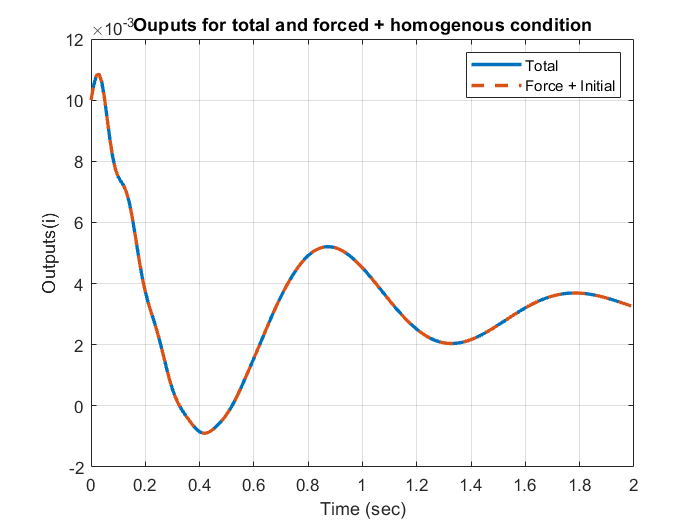

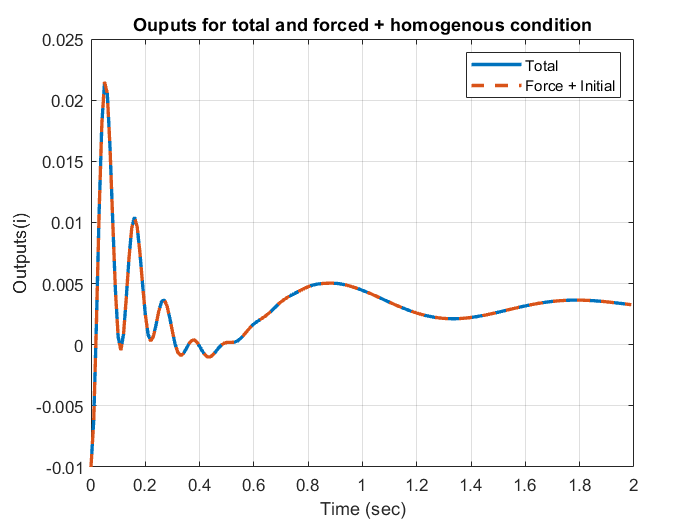

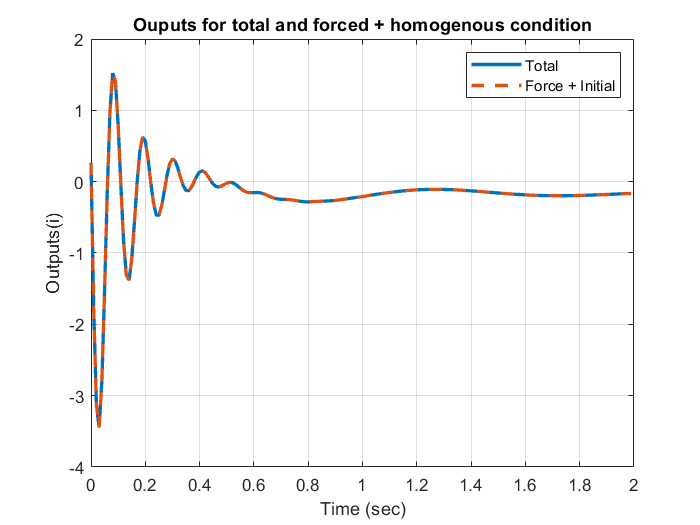

%-- Ouputs 
for i = 1:p
    figure;
plot(t,Y_t(:,i),'LineWidth',2); hold on;grid on;
plot(t,(Y_f(:,i)+Y_ic(:,i)),'--','LineWidth',2); 
xlabel('Time (sec)');ylabel('Outputs(i)');
legend('Total','Force + Initial');
title('Ouputs for total and forced + homogenous condition');
end

## Response for various Inputs

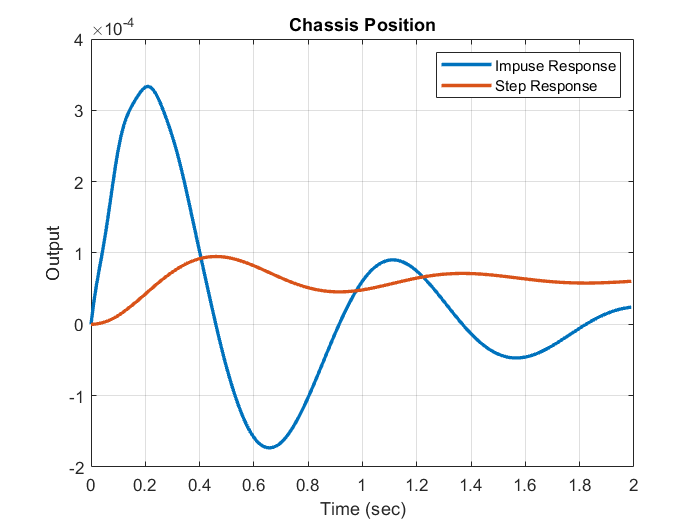

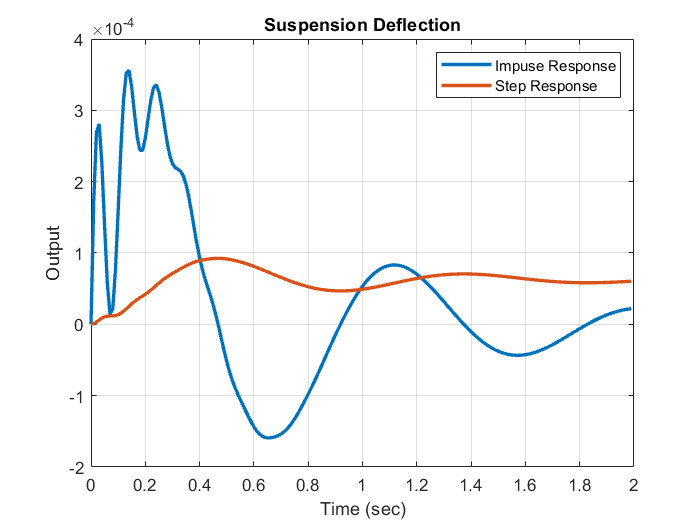

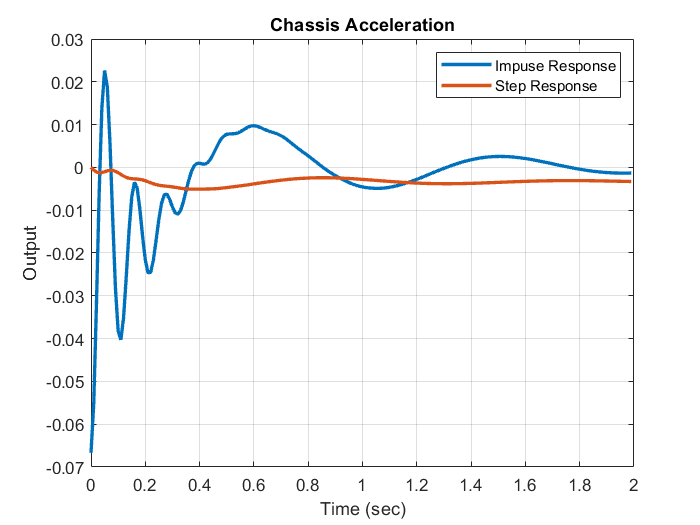

close all;
%-- Impulse and Step
for i = 1:p
    figure;
plot(t,Y_im(:,i),'LineWidth',2); hold on;grid on;
plot(t,Y_st(:,i),'LineWidth',2); hold on;grid on;
% Plots the i state for all time samples
title(Outputs(i));
xlabel('Time (sec)');ylabel('Output');
legend('Impuse Response', 'Step Response')
end

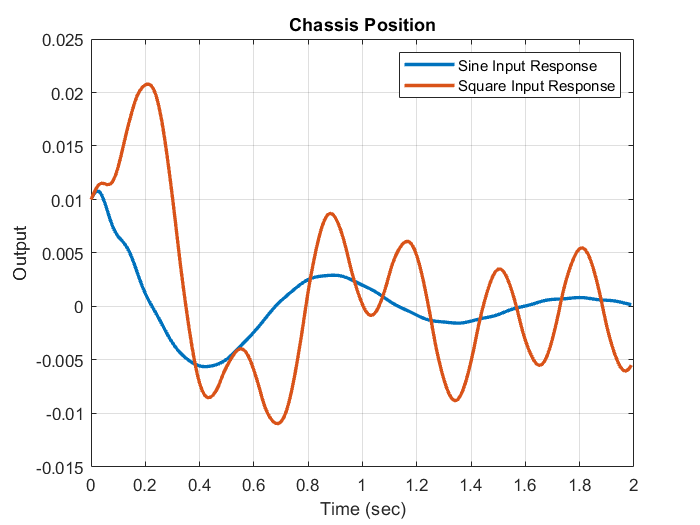

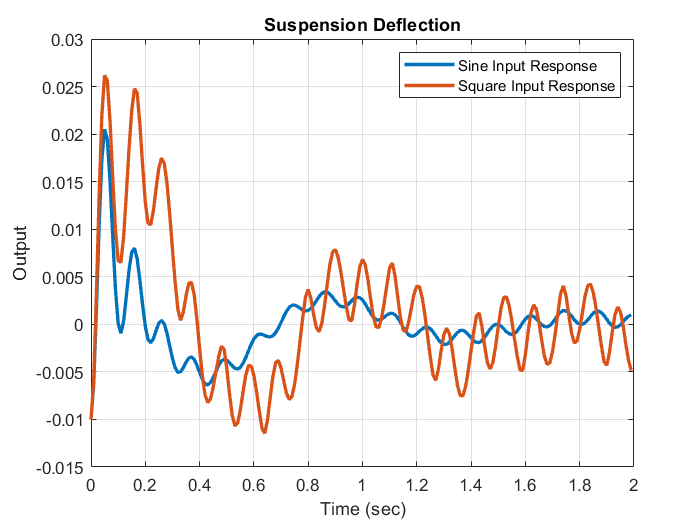

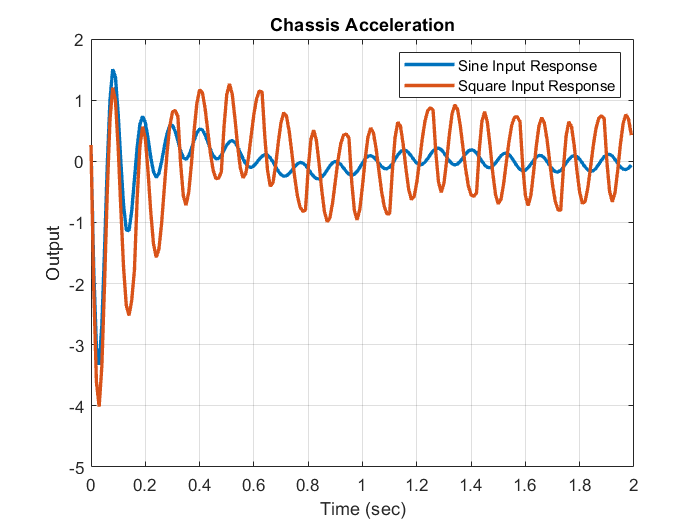

%-- Sine & Square
for i = 1:p
    figure;
plot(t,Y_sin(:,i),'LineWidth',2); hold on;grid on;
plot(t,Y_sqr(:,i),'LineWidth',2); hold on;grid on;
% Plots the i state for all time samples
title(Outputs(i));
xlabel('Time (sec)');ylabel('Output');
legend('Sine Input Response', 'Square Input Response')
end

## Pole Zero Plots

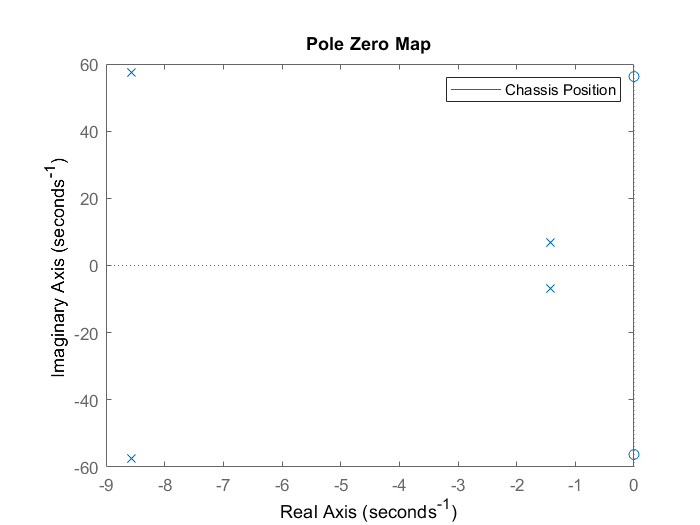

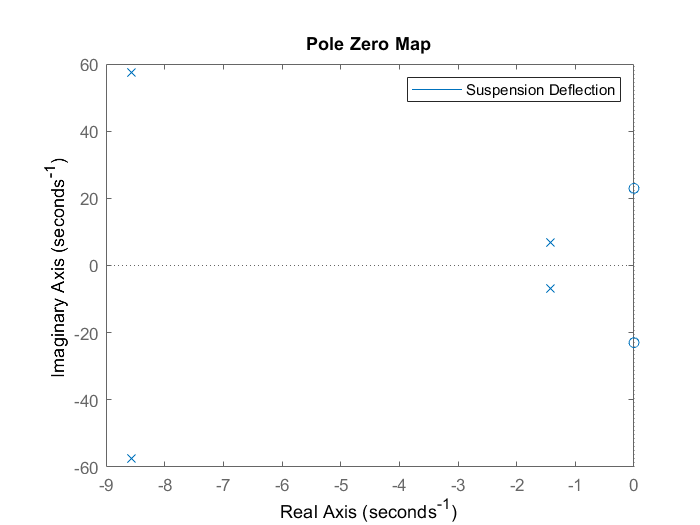

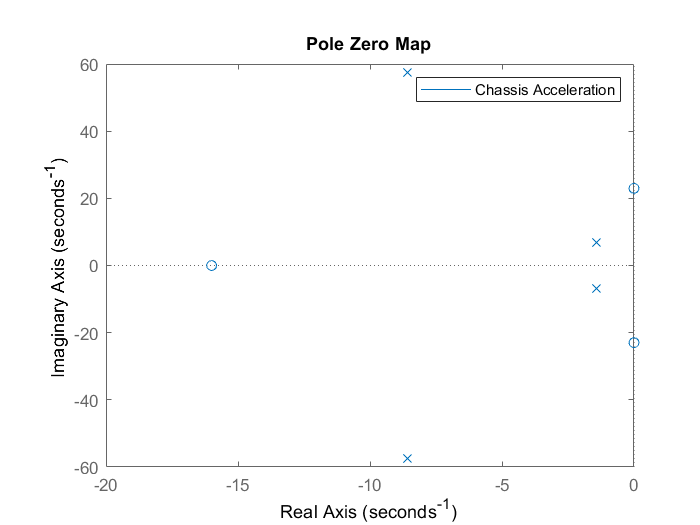

%---Outputs to Input
for i = 1:p
figure;
pzplot(ZPK_qcar(i,:)); % Plots the pole zero diagram of the system.
title('Pole Zero Map');
legend(Outputs(i));
end

## Root Locus Plots

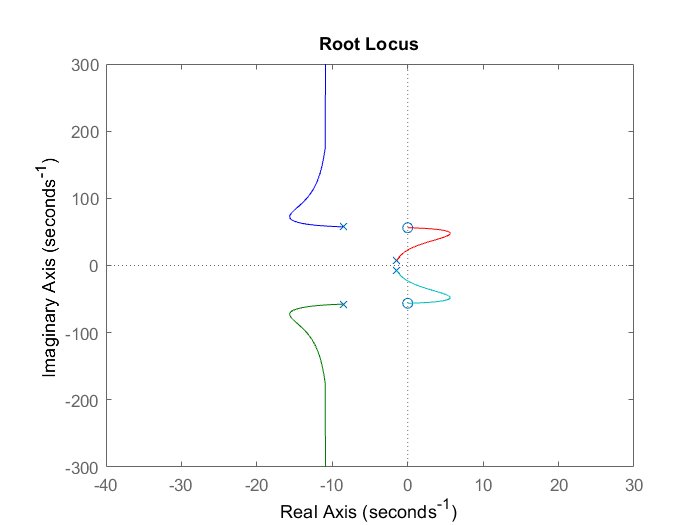

figure;
rlocus(ZPK_qcar(1));

## Response to Transfer Function

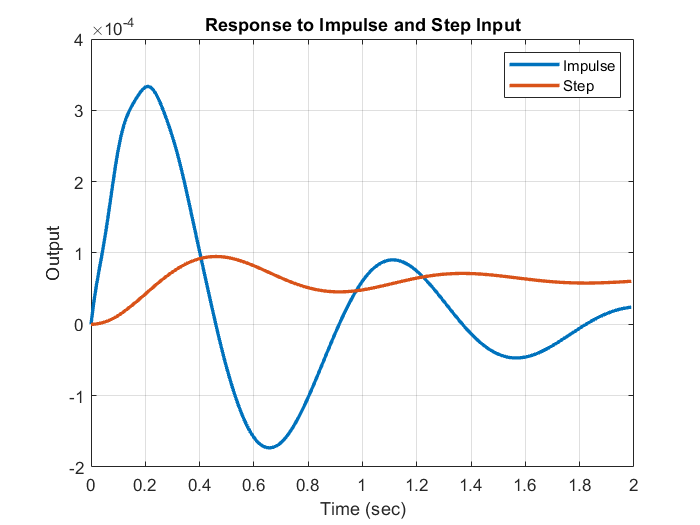

close all;
%--- Impulse & Step
figure;
plot(t,H1_qcar_imp,'LineWidth',2); grid on; hold on;
plot(t,H1_qcar_step,'LineWidth',2); grid on;
title(Outputs(1)); legend('Impulse','Step')
xlabel('Time (sec)');ylabel('Output');
title('Response to Impulse and Step Input');

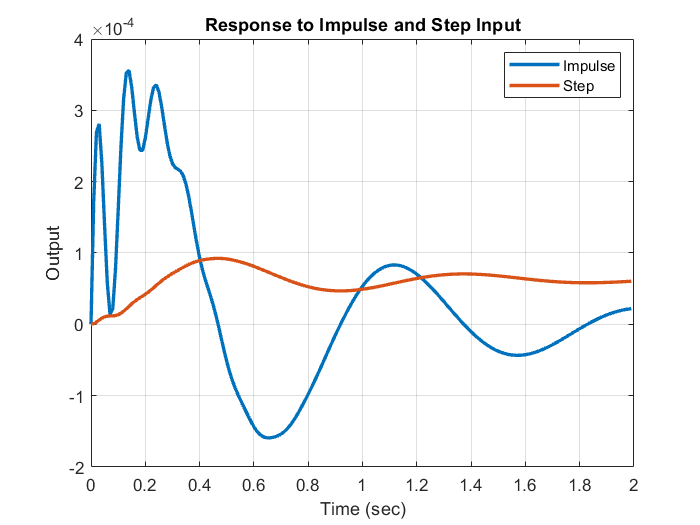

figure;
plot(t,H2_qcar_imp,'LineWidth',2); grid on; hold on;
plot(t,H2_qcar_step,'LineWidth',2); grid on;
title(Outputs(2)); legend('Impulse','Step')
xlabel('Time (sec)');ylabel('Output');
title('Response to Impulse and Step Input');

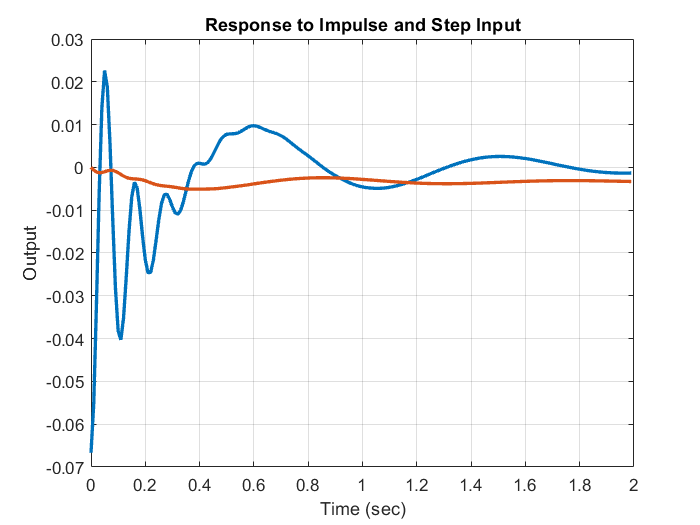

figure;
plot(t,H3_qcar_imp,'LineWidth',2); grid on; hold on;
plot(t,H3_qcar_step,'LineWidth',2); grid on;
title(Outputs(3));
xlabel('Time (sec)');ylabel('Output');
title('Response to Impulse and Step Input');

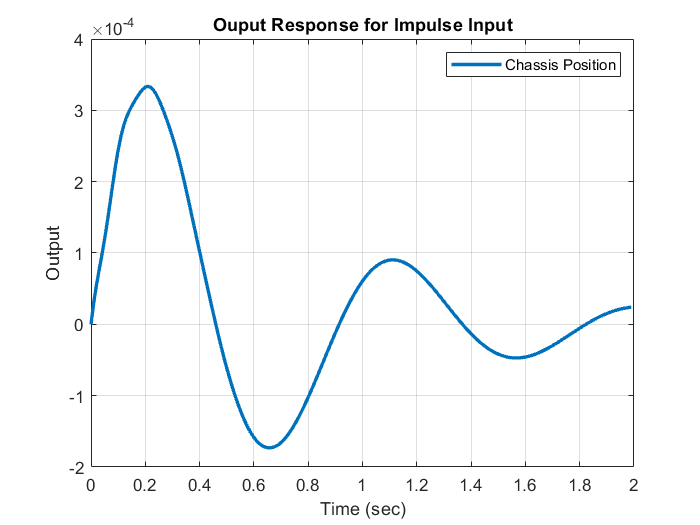

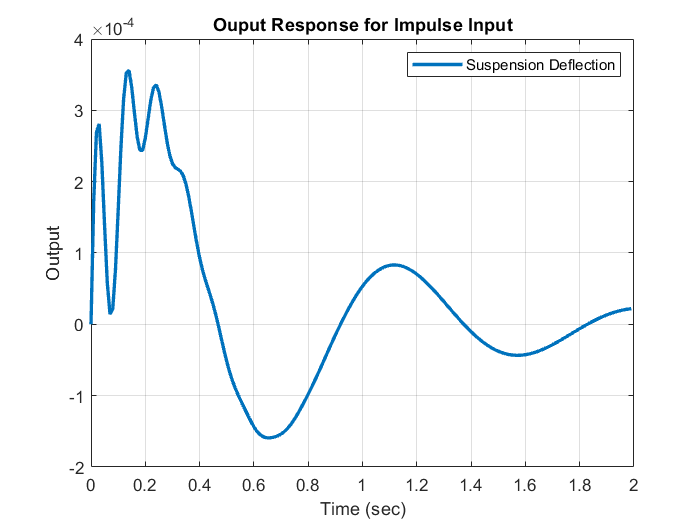

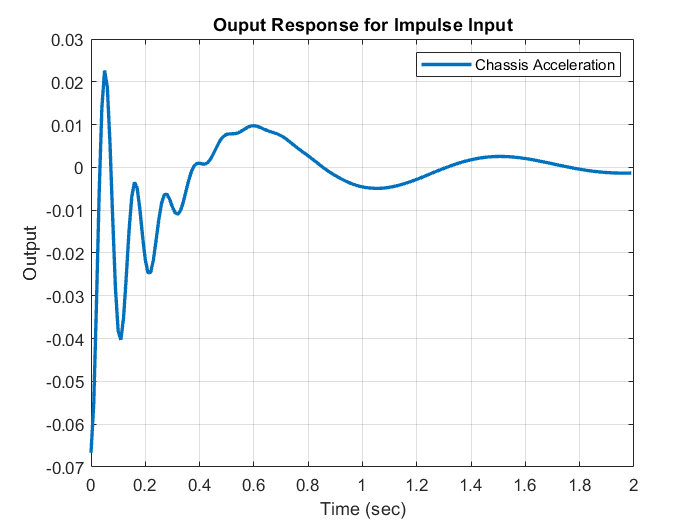

%-- Plot fot total Response
for i = 1:p
figure;
plot(t,H_qcar_imp(:,i),'LineWidth',2); grid on;   
xlabel('Time (sec)');ylabel('Output');
legend(Outputs(i))
title('Ouput Response for Impulse Input')
end    

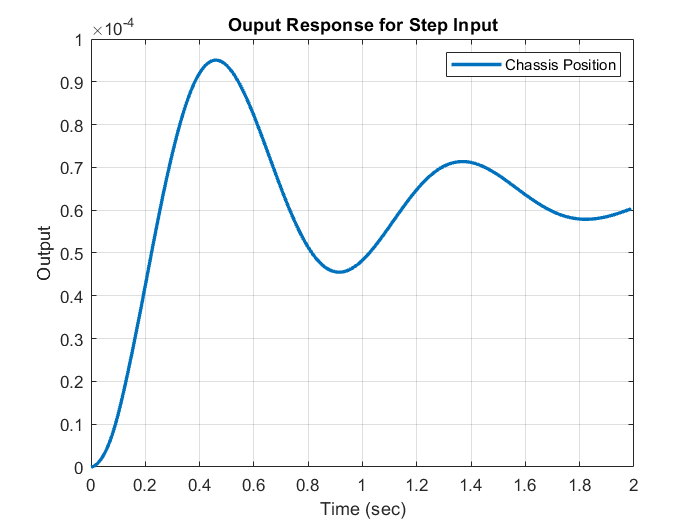

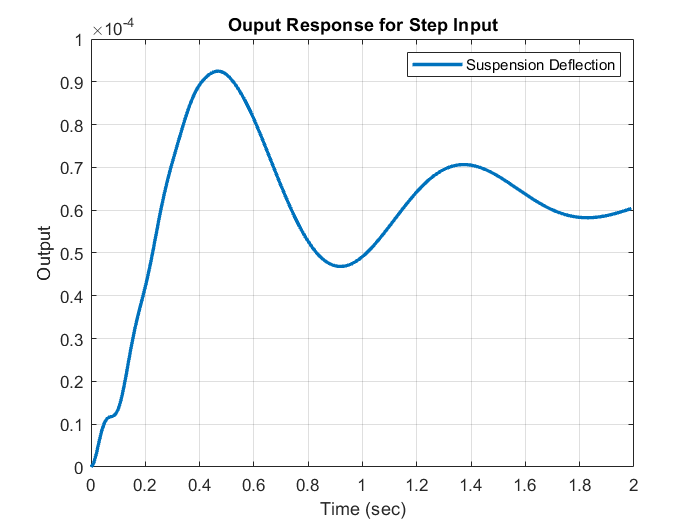

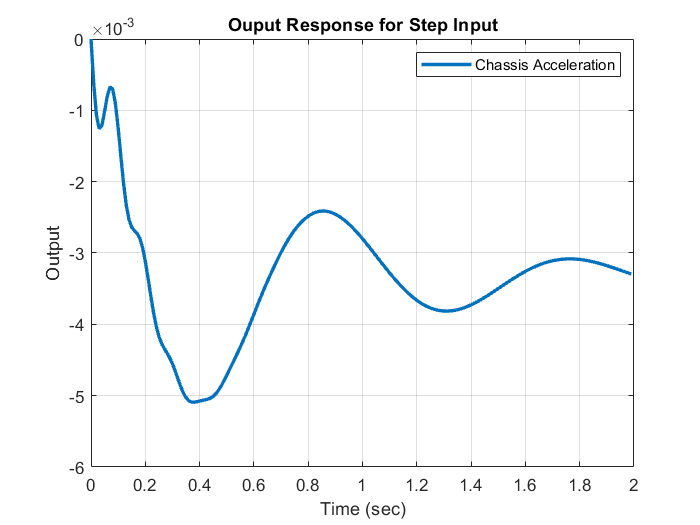

for i = 1:p
figure;
plot(t,H_qcar_step(:,i),'LineWidth',2); grid on;   
xlabel('Time (sec)');ylabel('Output');
legend(Outputs(i))
title('Ouput Response for Step Input')
end

## Comparing Response of TF and SS

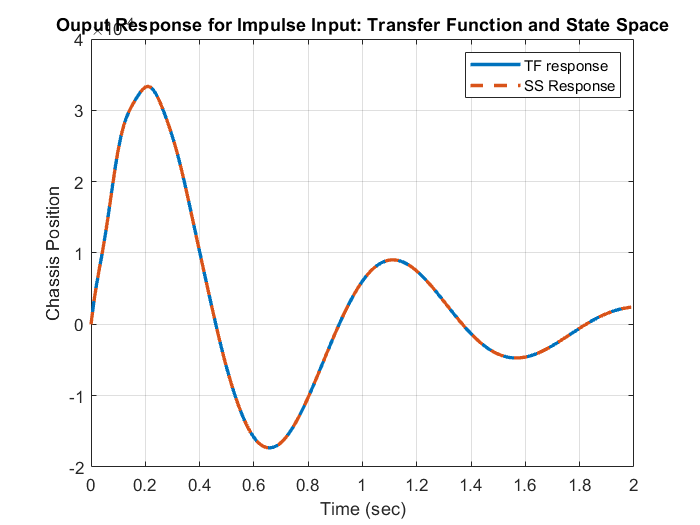

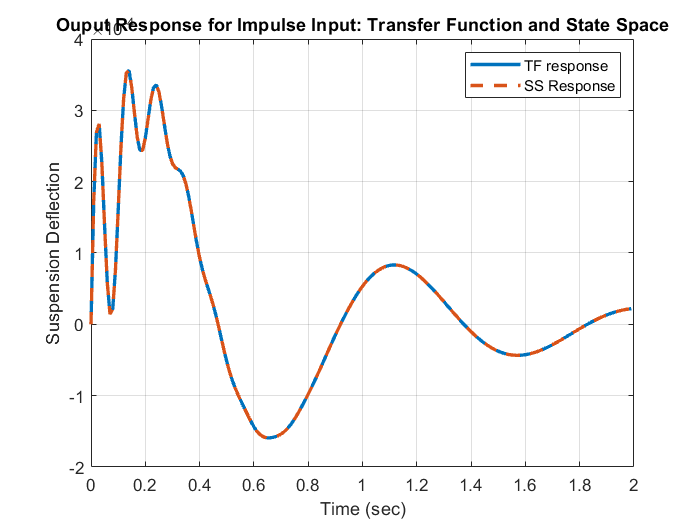

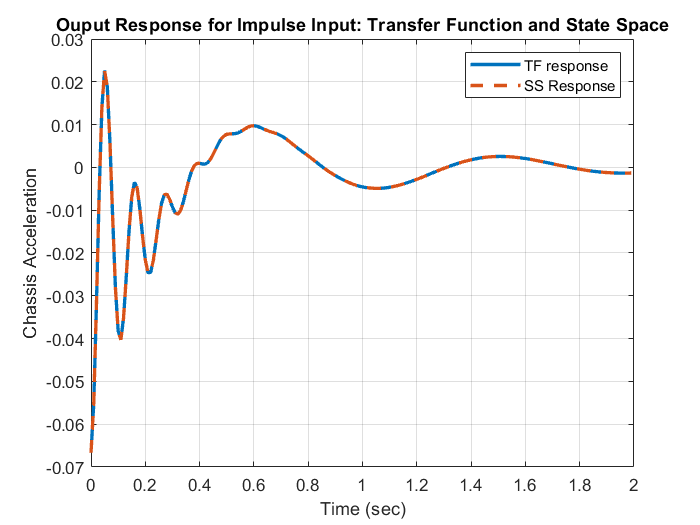

close all;
%-- Impulse Responses
for i = 1:p
figure;
plot(t,H_qcar_imp(:,i),'LineWidth',2); grid on;  hold on 
plot(t,Y_im(:,i),'--','LineWidth',2); hold on;grid on;
xlabel('Time (sec)');ylabel(Outputs(i));
legend('TF response','SS Response')
title('Ouput Response for Impulse Input: Transfer Function and State Space')
end

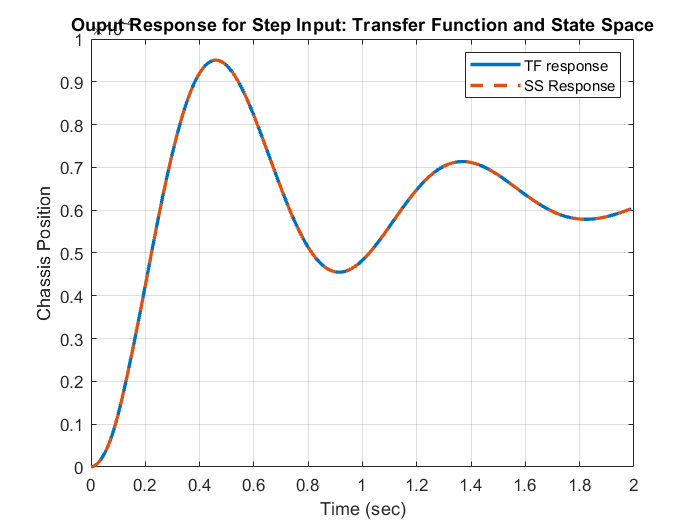

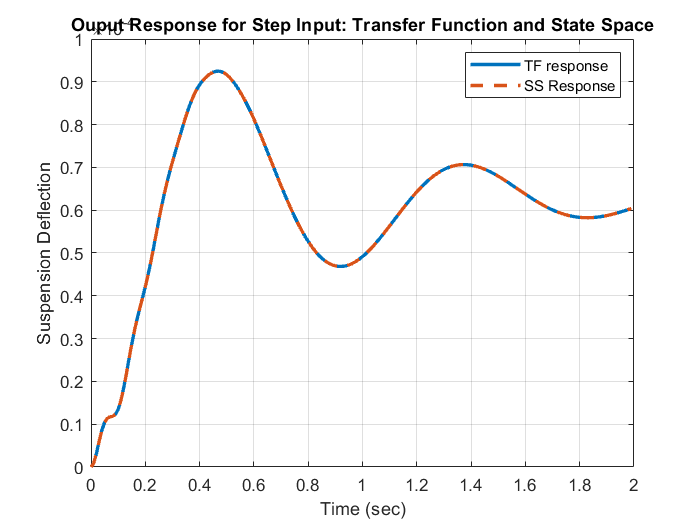

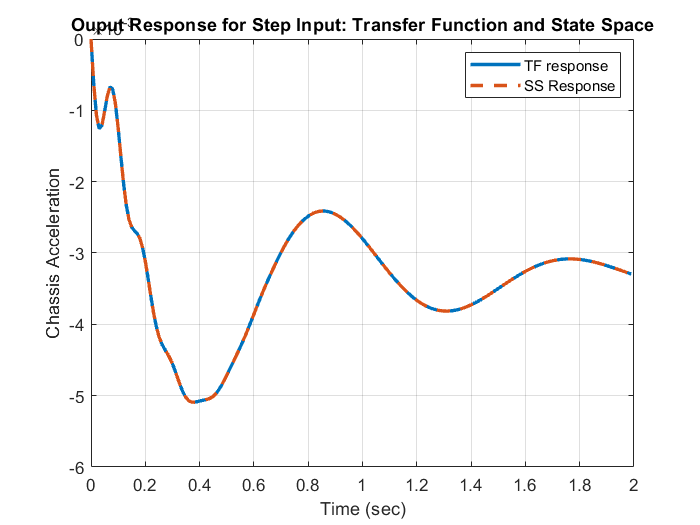

%-- Step Responses
for i = 1:p
figure;
plot(t,H_qcar_step(:,i),'LineWidth',2); grid on;  hold on 
plot(t,Y_st(:,i),'--','LineWidth',2); hold on;grid on;
xlabel('Time (sec)');ylabel(Outputs(i));
legend('TF response','SS Response')
title('Ouput Response for Step Input: Transfer Function and State Space')
end